# 03B. Steady states in 2D

## Mingyang Lu

## 1/7/2024

### Find intersections (see numericalR for detailed derivations)

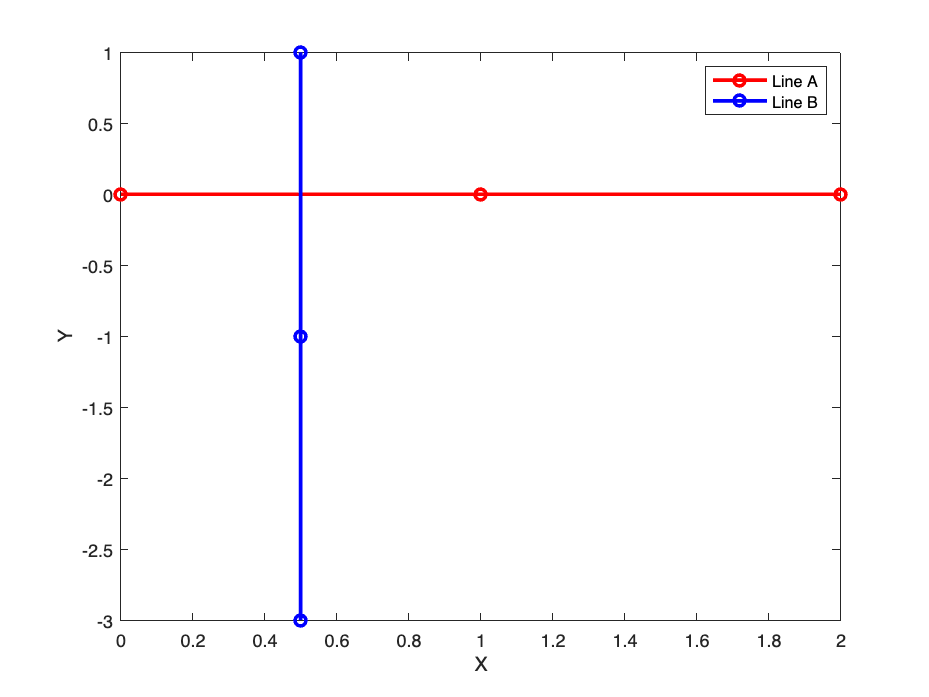

% test example with three points in each line. They intersect by the first segments.
lineA = [0, 0; 1, 0; 2, 0];
lineB = [0.5, 1; 0.5, -1; 0.5, -3];

figure;
plot(lineA(:, 1), lineA(:, 2), 'ro-', 'LineWidth', 2, 'DisplayName', 'Line A');
hold on;
plot(lineB(:, 1), lineB(:, 2), 'bo-', 'LineWidth', 2, 'DisplayName', 'Line B');
xlabel("X");
ylabel("Y");
legend('Location', 'northeast');
hold off;


disp(find_intersection(lineA, lineB, 1, 1)); % Intersect at (0.5, 0)

    0.5000         0    1.0000



disp(find_intersection(lineA, lineB, 1, 2)); % No intersection

    0.5000   -0.5000         0



disp(find_intersection(lineA, lineB, 2, 2)); % No intersection

   -0.5000   -0.5000         0



### Find all intersections of two nullclines in Part 3A[¶](http://localhost:8888/notebooks/03B.ipynb#Find-all-intersections-of-two-nullclines-in-Part-3A)

% Load nullcline data from Part 3A
null1 = load("null1_03A.csv");
null2 = load("null2_03A.csv");

% Find intersections
ss_all = find_intersection_all(null1, null2);
disp(ss_all);

  542.3736   35.2718
  189.9603  126.6468
   52.9083  361.5839



### Find all intersections (improved performance)

% Calculate dX/dt along the nullcline dY/dt = 0
dxdt_y_null_cell = arrayfun(@(idx) derivs_ts(0, null2(idx, :)), 1:size(null2, 1),'UniformOutput', false);
% Convert the cell array to a numeric array
dxdt_y_null = cell2mat(dxdt_y_null_cell);
dxdt = dxdt_y_null(1,:)';

% Calculate dY/dt along the nullcline dX/dt = 0
dydt_x_null_cell = arrayfun(@(idx) derivs_ts(0, null1(idx, :)), 1:size(null1, 1),'UniformOutput', false);
% Convert the cell array to a numeric array
dydt_x_null = cell2mat(dydt_x_null_cell);
dydt = dydt_x_null(2,:)';

% Find intersections
ss_all = find_intersection_all_fast(null1, null2, dxdt, dydt);
disp(ss_all);

  542.3736   35.2718
  189.9603  126.6468
   52.9083  361.5839



### Stability of steady states

ss_with_stability = zeros(size(ss_all, 1), 3);
for i = 1:size(ss_all, 1)
    ss_with_stability(i, :) = [ss_all(i, :), stability_2D(@derivs_ts, ss_all(i, :))];
end

results = array2table(ss_with_stability, 'VariableNames', {'X', 'Y', 'Stability'});
disp(results);

      X         Y       Stability
    ______    ______    _________

    542.37    35.272        1    
    189.96    126.65        3    
    52.908    361.58        1    



### Define MATLAB functions

1. Find intersection of two line segments

function intersection = find_intersection(lineA, lineB, nA, nB)
    dAX = lineA(nA + 1, 1) - lineA(nA, 1);
    dAY = lineA(nA + 1, 2) - lineA(nA, 2);

    dBX = lineB(nB + 1, 1) - lineB(nB, 1);
    dBY = lineB(nB + 1, 2) - lineB(nB, 2);

    dABX = lineB(nB, 1) - lineA(nA, 1);
    dABY = lineB(nB, 2) - lineA(nA, 2);

    d = dAX * dBY - dAY * dBX;

    alpha = (dABX * dBY - dABY * dBX) / d;
    beta = (dABX * dAY - dABY * dAX) / d;

    % check whether there is an intersection in between
    if (0 <= alpha && alpha <= 1) && (0 <= beta && beta <= 1)
        intersection = [(1 - alpha) * lineA(nA, 1) + alpha * lineA(nA + 1, 1), ...
                        (1 - alpha) * lineA(nA, 2) + alpha * lineA(nA + 1, 2), ...
                        1];
        % 1st and 2nd elements: X & Y
        % 3rd element: 1 means found, 0 means not found
    else
        intersection = [alpha, beta, 0];
        % 1st and 2nd elements: alpha & beta
    end
end

2. Search and find all intersections between two curves

function results = find_intersection_all(lineA, lineB)
    results = zeros(1000, 2);
    ind = 0;
    for i = 1:(size(lineA)-1)
        for j = 1:(size(lineB)-1)
            intersection = find_intersection(lineA, lineB, i, j);
            if (intersection(3) == 1)
                ind = ind + 1;
                results(ind,:) = intersection(1:2);
            end
        end
    end
    results = results(1:ind,:);
end

3. Inhibitory Hill function

% Same derivative function from Part 3A
function out = hill_inh(X, X_th, n)
    % inhibitory Hill function
    % X_th: Hill threshold, n: Hill coefficient
    a = (X / X_th).^n;
    out = 1 / (1 + a);
end

 4. Derivative function for a toggle switch circuit

function out = derivs_ts(t, Xs)
    X = Xs(1);
    Y = Xs(2);
    dxdt = 5 + 50 * hill_inh(Y, 100, 4) - 0.1 * X;
    dydt = 4 + 40 * hill_inh(X, 150, 4) - 0.12 * Y;
    out = [dxdt; dydt];
end

5. Search and find all intersections between two curves (improved)

function results = find_intersection_all_fast(lineA, lineB, dxdt, dydt)
    small = 1e-3; % used to allow some tolerance of numerical errors in detecting sign flipping
    lineA_ind = find(dydt .* [dydt(2:end); NaN] <= small);
    lineB_ind = find(dxdt .* [dxdt(2:end); NaN] <= small);
    
    results = zeros(1000, 2);
    ind = 0;
    for i = 1:size(lineA_ind)
        ind_i = lineA_ind(i);
        for j = 1:size(lineB_ind)
            ind_j = lineB_ind(j);
            intersection = find_intersection(lineA, lineB, ind_i, ind_j);
            if (intersection(3) == 1)
                ind = ind + 1;
                results(ind,:) = intersection(1:2);
            end
        end
    end
    results = results(1:ind,:);
end

6. Local stability analysis

function stability = stability_2D(derivs, ss)
    delta = 0.001;
    f_current = derivs(0, ss);
    f_plus_dx = derivs(0, ss + [delta, 0]);
    f_plus_dy = derivs(0, ss + [0, delta]);

    % Finite difference to approximate Jacobian
    dfxdx = (f_plus_dx(1) - f_current(1)) / delta;
    dfxdy = (f_plus_dy(1) - f_current(1)) / delta;
    dfydx = (f_plus_dx(2) - f_current(2)) / delta;
    dfydy = (f_plus_dy(2) - f_current(2)) / delta;

    jacobian = [dfxdx, dfxdy; dfydx, dfydy];
    lambdas = eig(jacobian);

    if any(imag(lambdas))
        if real(lambdas(1)) < 0
            stability = 4;  % stable spiral
        else
            stability = 5;  % unstable spiral
        end
    else
        if lambdas(1) < 0 && lambdas(2) < 0
            stability = 1;  % stable
        elseif lambdas(1) >= 0 && lambdas(2) >= 0
            stability = 2;  % unstable
        else
            stability = 3;  % saddle
        end
    end
end